# Seeding the random number generation

rng(1)
N=1000; % Length of the data
txname='tx_x6.dat';

## Generate complex white noise pulses TX Data


dat=sign(randn(N,1))+j*0; 
x_us=upsample(dat,100);
pulse=ones(100,1);
x=conv(x_us,pulse);

write_usrp_data_file(x,txname)

## Generate a cosine

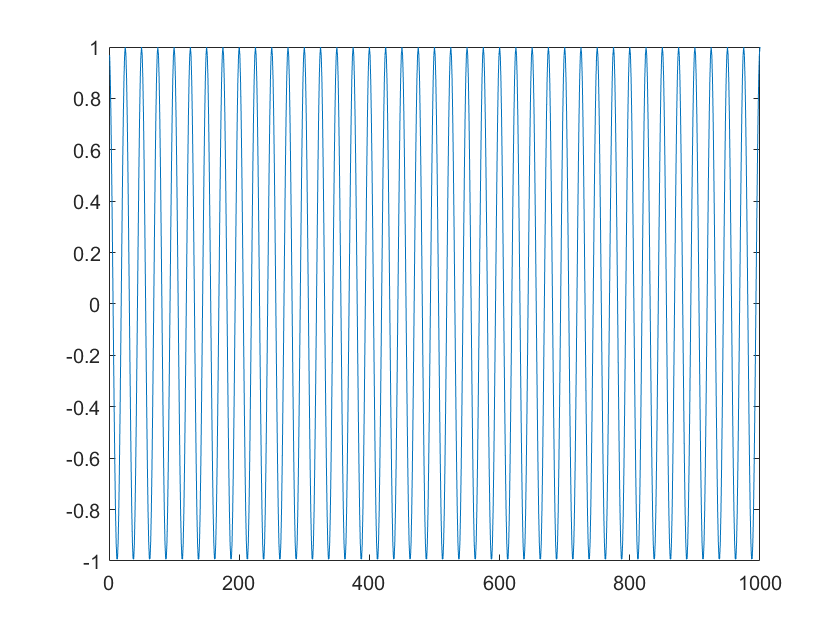

x=1:N;
cos_Dat=cos(2*pi/25*x);
write_usrp_data_file(cos_Dat)
plot(cos_Dat)


%write_usrp_data_file(x,txname)

err_rate = 0.4370